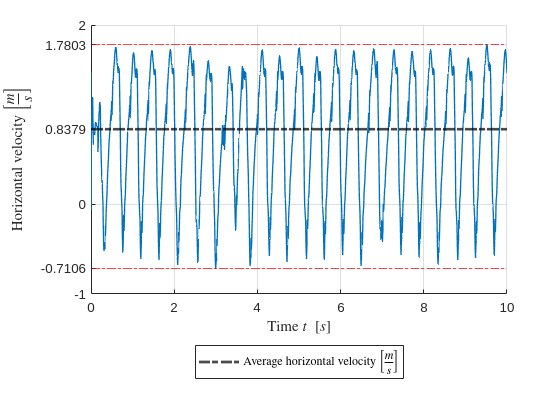

clear all

IC.limit.phi_knee = -1.9199; % -110 [deg]
IC.limit.phi_hip = 1.2217; % 70 [deg]
IC.limit.phi_com = 0.3491; % 20 [deg]
IC.limit.vphi_knee = 3; % 3.4907; % 200 [deg/s] IC.limit.vphi_hip;
IC.limit.vphi_hip = 2; % 5.2360; % 300 [deg/s] 2.0944; % 120 [deg/s]
IC.limit.vphi_com = IC.limit.vphi_hip;


solution = load('26-Feb-2023_201538_solution_1.6_15m.mat');
% cost = structfun(@(x) x.output.cost, solution);
% [~, best_idx] = min(cost)
% name = fieldnames(solution);

best_idx = 1;

mca = Fox_mca(solution.solution);
Fox_plot(solution, best_idx);



% dx = structfun(@(x) cat(1, x.com_kinematics.dx_com), solution);
% mean(dx)
% max(dx)
% min(dx)

% vx = structfun(@(x) x.touchdown.com.dx_com, solution);



% Fox_simulation(solution.(name{best_idx}).output.best_IC, 'on', solution.(name{best_idx}).output.GM_h, ...
%     solution.(name{best_idx}).output.prop_const, solution.(name{best_idx}).output.offset, IC.limit);


% single_iteration(solution.(name{best_idx}).output.best_IC, 'on', solution.(name{best_idx}).output.GM_h, ...
%     solution.(name{best_idx}).output.prop_const, solution.(name{best_idx}).output.offset, IC.limit);


                                                                                                                                            










% lambda_hip = structfun(@(x) cat(1, x.mechanical_cost_analysis.lambda_hip), solution);
% lambda_com = structfun(@(x) cat(1, x.mechanical_cost_analysis.lambda_com), solution);
% lambda_proj = structfun(@(x) cat(1, x.mechanical_cost_analysis.lambda_proj), solution);
% touchdown = structfun(@(x) cat(1, x.touchdown.time), solution);
% 
% figure
% hold on
% 
% plot(lambda_hip.time, lambda_hip.data, 'LineWidth', 2, 'Displayname', 'Lambda hip')
% plot(lambda_com.time, lambda_com.data, 'LineWidth', 2, 'Displayname', 'Lambda com')
% plot(lambda_proj.time, lambda_proj.data, 'LineWidth', 2, 'Displayname', 'Lambda proj')
% xline(touchdown.time, '-.b', 'LineWidth', 2, 'DisplayName', 'Touchdown')
% 
% xlabel('time [s]')
% ylabel('$\lambda [^\circ]$')
% legend show
% grid on